clear
% simultion of 4 metagriding

## constants


eta = 377; %ohm
f= 10*10^9; %Hz
c = 3*10^8; %m/s
lambda = c/f;
k = 2*pi/lambda;
omega = 2*pi*f;
w = 3*0.0254e-3; % meters, 3 mil
reff = w/4;
epsilon=8.85e-12;


## paramters


theta_in = 10*pi/180; %rads
theta_out = 70*pi/180;% rads
phi = 25*pi/180; % rads
Ein = 1;

sinin = sin(theta_in);
cosin = cos(theta_in);
sinout = sin(theta_out);
cosout = cos(theta_out);

Zin = eta/cos(theta_in);
Zout = eta/cos(theta_out);
Lambda = lambda/abs(sinout-sinin);


## Optimization parameters

x0=[Lambda/6,Lambda/3,Lambda/2,2*Lambda/3,5*Lambda/6,Lambda,lambda/6,lambda/3,lambda/2,2*lambda/3,5*lambda/6,lambda];
N=2000;
save('var.mat');

## Optimization

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      13    2.486333e-04    3.416e-02    3.916e-02
    1      27    5.027768e-04    1.504e-02    4.461e-01    1.953e-02


    2      41    5.268597e-04    8.142e-03    4.165e-01    1.132e-02


    3      54    1.203428e-03    0.000e+00    4.986e-01    1.310e-02


    4      68    6.549962e-04    0.000e+00    2.051e+00    3.818e-03


    5      81    2.567535e-03    0.000e+00    6.604e+00    3.476e-03


    6      94    6.247303e-04    0.000e+00    4.989e-01    2.936e-03


    7     107    1.518433e-03    0.000e+00    1.310e+00    3.507e-03


    8     120    7.283546e-04    0.000e+00    4.484e-01    1.426e-03


    9     133    7.410308e-04    0.000e+00    5.020e-01    8.005e-04


   10     146    8.747884e-04    0.000e+00    5.124e-01    1.295e-03


   11     159    6.246710e-04    0.000e+00    3.252e-01    6.458e-04


   12     172    5.508873e-04    0.000e+00    2.319e-01    2.354e-04


   13     194    5.465354e-04    0.000e+00    2.062e-02    1.452e-05


   14     207    4.779536e-04    0.000e+00    6.637e-01    4.472e-04


   15     220    4.461891e-04    0.000e+00    2.568e-01    4.360e-04


   16     234    4.648387e-04    0.000e+00    8.480e-01    3.585e-04


   17     249    4.590365e-04    0.000e+00    2.450e-01    4.372e-05


   18     262    4.578795e-04    0.000e+00    6.750e-01    3.993e-05


   19     277    4.573919e-04    0.000e+00    2.461e-01    6.951e-06


   20     290    4.571915e-04    0.000e+00    2.442e-01    1.648e-05


   21     304    4.582024e-04    0.000e+00    2.756e-01    2.163e-05


   22     319    4.580301e-04    0.000e+00    6.798e-01    6.102e-06


   23     333    4.580600e-04    0.000e+00    2.473e-01    1.119e-05


   24     346    4.582431e-04    0.000e+00    2.485e-01    6.067e-06


   25     362    4.581999e-04    0.000e+00    6.823e-01    1.521e-06


   26     375    4.581055e-04    0.000e+00    4.789e-01    4.022e-06


   27     394    4.581785e-04    0.000e+00    2.076e-02    2.207e-06


   28     407    4.284301e-04    0.000e+00    3.446e-01    3.654e-04


   29     421    3.335846e-04    0.000e+00    2.836e-01    1.149e-03


   30     435    3.417844e-04    0.000e+00    1.244e-01    5.803e-04


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
   31     448    3.437020e-04    0.000e+00    1.334e-01    2.905e-04


   32     464    3.396666e-04    0.000e+00    3.063e-01    1.355e-04


   33     477    3.335127e-04    0.000e+00    1.236e-01    8.716e-05


   34     490    3.373654e-04    0.000e+00    3.003e-01    4.963e-05


   35     503    3.367003e-04    0.000e+00    2.966e-01    4.316e-05


   36     516    3.316305e-04    0.000e+00    2.814e-01    1.221e-04


   37     540    3.316127e-04    0.000e+00    5.272e-03    3.532e-07


   38     553    2.434719e-04    0.000e+00    6.282e-02    1.413e-03


   39     566    2.165895e-04    0.000e+00    5.428e-02    3.980e-04


   40     579    2.092079e-04    0.000e+00    5.197e-02    2.680e-04


   41     592    2.055593e-04    0.000e+00    5.154e-02    1.119e-04


   42     606    2.023807e-04    0.000e+00    5.325e-02    1.945e-04


   43     627    2.021449e-04    0.000e+00    1.320e-03    2.851e-05


   44     646    1.951282e-04    0.000e+00    6.168e-02    6.593e-04


   45     660    1.740066e-04    0.000e+00    6.394e-02    4.625e-04


   46     674    1.218011e-04    0.000e+00    2.906e-02    1.882e-03


   47     688    1.233775e-04    0.000e+00    7.190e-02    6.686e-04


   48     704    1.232372e-04    0.000e+00    3.230e-02    2.059e-04


   49     719    1.126331e-04    0.000e+00    3.831e-02    1.125e-03


   50     732    1.124683e-04    0.000e+00    2.408e-02    5.402e-04


   51     746    1.181276e-04    0.000e+00    4.221e-02    6.155e-04


   52     759    1.153252e-04    0.000e+00    3.733e-02    2.368e-04


   53     774    1.142733e-04    0.000e+00    3.062e-02    1.326e-04


   54     790    1.139825e-04    0.000e+00    3.928e-02    1.951e-05


   55     803    1.129468e-04    0.000e+00    3.760e-02    1.151e-04


   56     816    1.136915e-04    0.000e+00    3.807e-02    6.625e-05


   57     837    1.136824e-04    0.000e+00    1.864e-02    2.686e-05


   58     850    1.177810e-04    0.000e+00    3.804e-02    3.139e-04


   59     863    1.193089e-04    0.000e+00    6.702e-02    7.720e-04


   60     876    1.152921e-04    0.000e+00    3.458e-02    3.696e-04


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
   61     889    1.156703e-04    0.000e+00    3.524e-02    2.883e-04


   62     903    1.150860e-04    0.000e+00    5.574e-02    1.521e-04


   63     916    1.150291e-04    0.000e+00    3.515e-02    2.356e-04


   64     929    1.149960e-04    0.000e+00    3.551e-02    6.347e-05


   65     945    1.150873e-04    0.000e+00    6.028e-02    2.737e-05


   66     958    1.151488e-04    0.000e+00    6.040e-02    1.129e-04


   67     971    1.161030e-04    0.000e+00    3.685e-02    2.931e-04


   68     986    1.151967e-04    0.000e+00    2.770e-02    8.283e-05


   69    1002    1.150144e-04    0.000e+00    1.153e-01    1.080e-04


   70    1016    1.142225e-04    0.000e+00    8.609e-02    1.178e-04


   71    1029    1.148791e-04    0.000e+00    3.586e-02    1.247e-04


   72    1042    1.153616e-04    0.000e+00    3.599e-02    8.710e-05


   73    1063    1.153520e-04    0.000e+00    3.435e-02    5.567e-06


   74    1077    1.152005e-04    0.000e+00    3.440e-02    9.579e-06


   75    1099    1.151898e-04    0.000e+00    8.977e-03    1.759e-06


   76    1113    1.151768e-04    0.000e+00    9.022e-03    1.209e-06


   77    1133    1.151686e-04    0.000e+00    2.178e-02    8.088e-07


   78    1147    1.151636e-04    0.000e+00    2.179e-02    6.323e-07


   79    1168    1.151619e-04    0.000e+00    3.435e-02    2.196e-07


   80    1182    1.151608e-04    0.000e+00    3.435e-02    1.626e-07


   81    1200    1.151593e-04    0.000e+00    8.978e-03    4.434e-07


   82    1214    1.151545e-04    0.000e+00    8.992e-03    5.923e-07


   83    1231    1.151453e-04    0.000e+00    2.179e-02    1.500e-06


   84    1245    1.151510e-04    0.000e+00    6.399e-02    1.285e-06


   85    1266    1.151460e-04    0.000e+00    6.522e-02    3.972e-07


   86    1287    1.151458e-04    0.000e+00    8.989e-03    1.937e-07


   87    1301    1.151455e-04    0.000e+00    5.471e-02    1.008e-07


   88    1321    1.151453e-04    0.000e+00    2.179e-02    4.925e-08


   89    1335    1.151450e-04    0.000e+00    2.179e-02    3.095e-08


   90    1355    1.151447e-04    0.000e+00    2.558e-02    1.203e-08


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
   91    1376    1.151446e-04    0.000e+00    4.078e-02    5.287e-09


   92    1397    1.151446e-04    0.000e+00    3.935e-02    6.700e-10


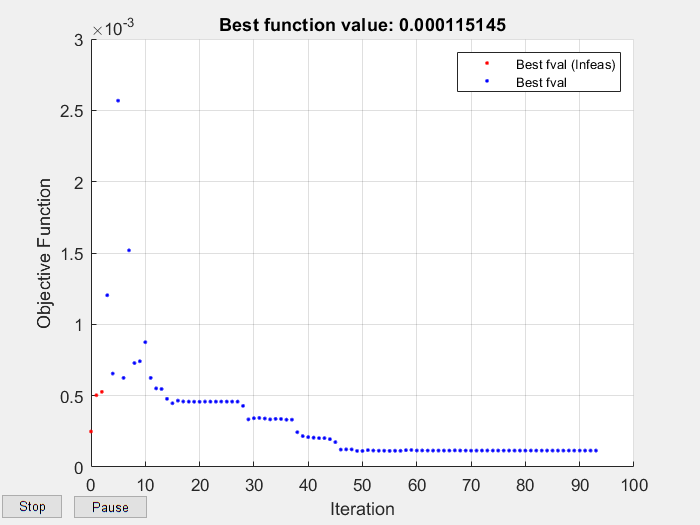


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% Set nondefault solver options
options = optimoptions('fmincon','Display','iter','PlotFcn',...
    'optimplotfvalconstr');

% Solve
[solution,objectiveValue] = fmincon(@objectiveFcn,x0,[],[],[],[],[],[],...
    @constraintFcn,options);


% Clear variables
clearvars options

## results

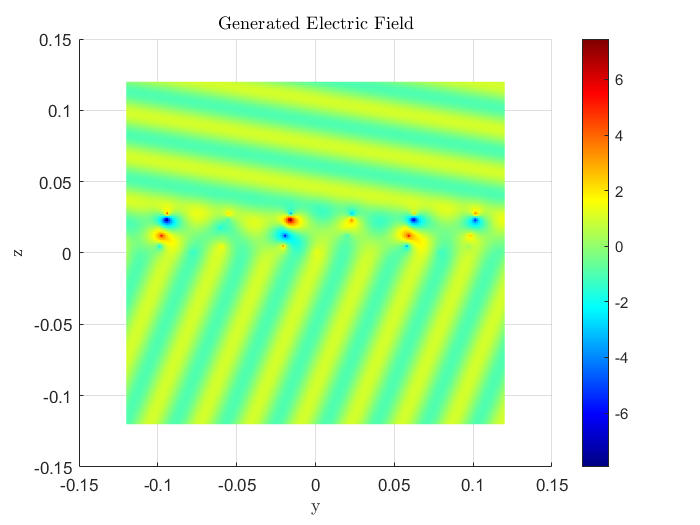

Ds = [0 solution(1:5)];
Hs = [0 solution(6:10)];
Is =  FindCurrents(Ds,Hs,Lambda,Ein,Zin,Zout,theta_in,theta_out,k,phi);
Fields = FindElectricFiield(Lambda,k,eta,theta_in,Ein,Ds,Hs,Is,reff,N);
Zs= Fields./Is;
M = 200; %plot resolution
y = linspace(-4*lambda,4*lambda, M)'; % colum vector
z = linspace(-4*lambda,4*lambda, M); % row vector
[TotalElectricFieldMatrix, GeneratedElectricFieldMatrix] = ElectricFieldYZ(Is,Ds,Hs,k,Lambda,y,z,theta_in,Ein,N,eta,theta_out);
PlotField(GeneratedElectricFieldMatrix,y,z,'Generated Electric Field');

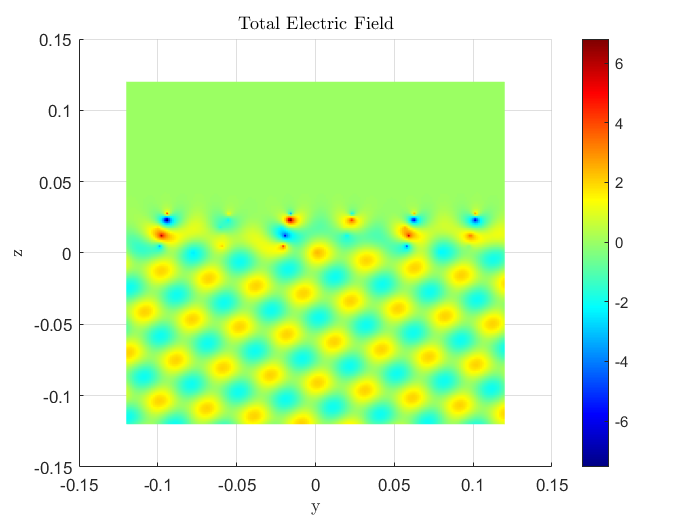

PlotField(TotalElectricFieldMatrix,y,z,'Total Electric Field');

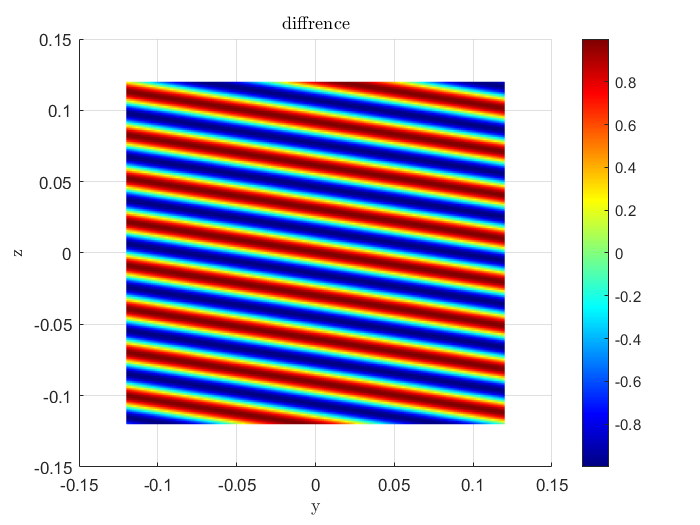

PlotField(TotalElectricFieldMatrix-GeneratedElectricFieldMatrix,y,z,'diffrence');

## normalization

UnitI=Lambda/eta*Ein;
IsNorm=Is/UnitI;
DsNorm=Ds/Lambda;
HsNorm=Hs/Lambda;
PowerIn=1/2/eta*Ein^2*Lambda*cosin;
PowerLost=(1/2*abs(Is).^2).*real(Zs);
NormPowerLost=PowerLost/PowerIn;

## optimization function

function f = objectiveFcn(optimInput)

load('var.mat');
% Edit the lines below with your calculation
D2 = optimInput(1);
D3 = optimInput(2);
D4 = optimInput(3);
D5 = optimInput(4);
D6= optimInput(5);
H2 = optimInput(6);
H3 = optimInput(7);
H4 = optimInput(8);
H5 = optimInput(9);
H6 = optimInput(10);

Ds= [0 D2 D3 D4 D5 D6];
Hs= [0 H2 H3 H4 H5 H6];
Is = FindCurrents(Ds,Hs,Lambda,Ein,Zin,Zout,theta_in,theta_out,k,phi);
Fields = FindElectricFiield(Lambda,k,eta,theta_in,Ein,Ds,Hs,Is,reff,N);
Zs= Fields./Is;
f= sum(abs((1/2*abs(Is).^2).*real(Zs)));
%f= sum(abs(real(Zs)./imag(Zs)));
end


## costrains


function [c,ceq] = constraintFcn(optimInput)
load('var.mat');
% Example:
% Constrain a solution to the region
% h2 <= h3
% h3 <= h4
% y = x^3

% Edit the lines below with your calculation
% Note, if no inequality constraints, specify c = []
% Note, if no equality constraints, specify ceq = []
D2 = optimInput(1);
D3 = optimInput(2);
D4 = optimInput(3);
D5 = optimInput(4);
D6= optimInput(5);
H2 = optimInput(6);
H3 = optimInput(7);
H4 = optimInput(8);
H5 = optimInput(9);
H6 = optimInput(10);

c(1) = H2 - H3;
c(2) = H3 - H4;
c(3) = H4 - H5;
c(4) = H5 - H6;
c(5) = - H2;
c(6) = - D2;
c(7) = - D3;
c(8) = - D4;
c(9) = - D5;
c(10) = - D6;
c(11) = D2 - Lambda;
c(12) = D3 - Lambda;
c(13) = D4 - Lambda;
c(14) = D5 - Lambda;
c(15) = D6 - Lambda;
c(16) = H6 - lambda;
ceq = [];
end
